## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 65);

% Specify sheet and range
opts.Sheet = "Supplementary material_final";
opts.DataRange = "A3:BM132";

% Specify column names and types
opts.VariableNames = ["VarName1", "Ageyears", "Gender", "Var4", "AgeOfDiseaseOnsetyears", "DurationOfDiseaseFromFirstSymptomsyears", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "UPDRSIIITotal", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41", "EST_R", "RST_R", "AST_R", "DPI_R", "DVI_R", "GVI_R", "DUS_R", "DUF_R", "RLR_R", "PIR_R", "RSR_R", "LRE_R", "EST_M", "RST_M", "AST_M", "DPI_M", "DVI_M", "GVI_M", "DUS_M", "DUF_M", "RLR_M", "PIR_M", "RSR_M", "LRE_M"];
opts.SelectedVariableNames = ["VarName1", "Ageyears", "Gender", "AgeOfDiseaseOnsetyears", "DurationOfDiseaseFromFirstSymptomsyears", "UPDRSIIITotal", "EST_R", "RST_R", "AST_R", "DPI_R", "DVI_R", "GVI_R", "DUS_R", "DUF_R", "RLR_R", "PIR_R", "RSR_R", "LRE_R", "EST_M", "RST_M", "AST_M", "DPI_M", "DVI_M", "GVI_M", "DUS_M", "DUF_M", "RLR_M", "PIR_M", "RSR_M", "LRE_M"];
opts.VariableTypes = ["string", "double", "categorical", "char", "double", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["VarName1", "Var4", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["VarName1", "Gender", "Var4", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("data.xls", opts, "UseExcel", false);
clear opts


groups(1:30,1) = categorical("PD");
groups(31:80,1) = categorical("RBD");
groups(81:130,1) = categorical("HC");
gender = data.Gender;

data(:,7:end) = filloutliers(data(:,7:end),nan);



## UPDRS t-test

normality = ["Group" "UPDRSIII"];
normality(2,1) = "PD";
normality(3,1) = "RBD";


[~,normality(2,2),~] = swtest(rmoutliers(x1),0.05);
[~,normality(3,2),~] = swtest(rmoutliers(x2),0.05);
normality

[h,p,~,stats] = ttest2(data.UPDRSIIITotal(1:30),data.UPDRSIIITotal(31:80))

H0: Není rozdíl mezi UPDRSIII u PD a RBD skupiny.

H1 :Je rozdíl mezi UPDRSIII u PD a RBD skupiny.

Zamítáme H0: t(78) = 7.94, p < 0.001

U RBD je zhoršení motoriky mnohem menší než u PD.

## Normality testing

normality = ["Group" data.Properties.VariableNames(7:end)];
normality = cellstr(normality)

normality = 1×25 cell array
    {'Group'}    {'EST_R'}    {'RST_R'}    {'AST_R'}    {'DPI_R'}    {'DVI_R'}    {'GVI_R'}    {'DUS_R'}    {'DUF_R'}    {'RLR_R'}    {'PIR_R'}    {'RSR_R'}    {'LRE_R'}    {'EST_M'}    {'RST_M'}    {'AST_M'}    {'DPI_M'}    {'DVI_M'}    {'GVI_M'}    {'DUS_M'}    {'DUF_M'}    {'RLR_M'}    {'PIR_M'}    {'RSR_M'}    {'LRE_M'}


normality{2,1} = "PD";
normality{3,1} = "RBD";
normality{4,1} = "HC";
normality{5,1} = "Combined";

for i = 1:24
    x = data(:,i+6);
    x1 = x{1:30,:};
    x2 = x{31:80,:};
    x3 = x{81:130,:};
    [~,normality{2,i+1},~] = swtest(rmoutliers(x1),0.05);
    [~,normality{3,i+1},~] = swtest(rmoutliers(x2),0.05);
    [~,normality{4,i+1},~] = swtest(rmoutliers(x3),0.05);
    [~,normality{5,i+1},~] = swtest(rmoutliers([x1 ;x2; x3]),0.05);


end
normality

normality = 5×25 cell array
    {'Group'     }    {'EST_R' }    {'RST_R' }    {'AST_R' }    {'DPI_R' }    {'DVI_R' }    {'GVI_R' }    {'DUS_R'     }    {'DUF_R' }    {'RLR_R' }    {'PIR_R' }    {'RSR_R' }    {'LRE_R' }    {'EST_M' }    {'RST_M' }    {'AST_M' }    {'DPI_M' }    {'DVI_M' }    {'GVI_M' }    {'DUS_M'     }    {'DUF_M' }    {'RLR_M' }    {'PIR_M'     }    {'RSR_M' }    {'LRE_M' }
    {["PD"      ]}    {[0.3433]}    {[0.6396]}    {[0.5345]}    {[0.4206]}    {[0.0417]}    {[0.7567]}    {[    0.0764]}    {[0.3000]}    {[0.2062]}    {[0.4378]}    {[0.3079]}    {[0.0643]}    {[0.7167]}    {[0.2899]}    {[0.7984]}    {[0.3544]}    {[0.1019]}    {[0.3800]}    {[    0.0334]}    {[0.2829]}    {[0.4513]}    {[    0.0293]}    {[0.7829]}    {[0.8217]}
    {["RBD"     ]}    {[0.0865]}    {[0.2612]}    {[0.0429]}    {[0.0220]}    {[0.7959]}    {[0.9489]}    {[    0.0056]}    {[0.5894]}    {[0.4578]}    {[0.8119]}    {[0.7356]}    {[0.1203]}    {[0.2151]}    {[0.1878]}    {[0.8285]}    {[

Zahodit: EST, DUS

## Homogenity testing

homogenity = [data.Properties.VariableNames(7:end)];

for i = 1:24
    x = data{:,i+6};
    
    homogenity{2,i} = vartestn(x,groups,"Display","off");

end
homogenity

homogenity = 2×24 cell array
    {'EST_R' }    {'RST_R' }    {'AST_R' }    {'DPI_R' }    {'DVI_R' }    {'GVI_R' }    {'DUS_R' }    {'DUF_R' }    {'RLR_R' }    {'PIR_R' }    {'RSR_R' }    {'LRE_R' }    {'EST_M' }    {'RST_M' }    {'AST_M' }    {'DPI_M' }    {'DVI_M' }    {'GVI_M' }    {'DUS_M' }    {'DUF_M' }    {'RLR_M' }    {'PIR_M' }    {'RSR_M' }    {'LRE_M' }
    {[0.1210]}    {[0.9357]}    {[0.2084]}    {[0.0773]}    {[0.0536]}    {[0.6309]}    {[0.6413]}    {[0.9498]}    {[0.2920]}    {[0.6798]}    {[0.2428]}    {[0.9034]}    {[0.1226]}    {[0.7066]}    {[0.0633]}    {[0.0238]}    {[0.3448]}    {[0.7944]}    {[0.5677]}    {[0.3442]}    {[0.2245]}    {[0.8823]}    {[0.8833]}    {[0.5473]}


Zahodit: EST, DPI, DVI, RSR, LRE

## ANOVA

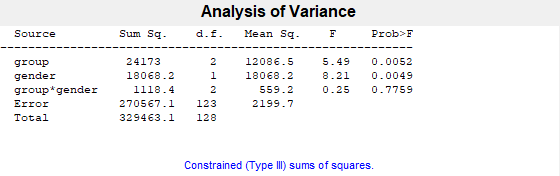

data_adj(:,1) = data(:,20); data_adj.Properties.VariableNames{1,1} = 'RST_M';
data_adj(:,2) = data(:,21); data_adj.Properties.VariableNames{1,2} = 'AST_M';
data_adj(:,3) = data(:,24); data_adj.Properties.VariableNames{1,3} = 'GVI_M';
data_adj(:,4) = data(:,26); data_adj.Properties.VariableNames{1,4} = 'DUF_M';
data_adj(:,5) = data(:,27); data_adj.Properties.VariableNames{1,5} = 'RLR_M';
data_adj(:,6) = data(:,28); data_adj.Properties.VariableNames{1,6} = 'PIR_M';

[~,~,stats] = anovan(data_adj.RST_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

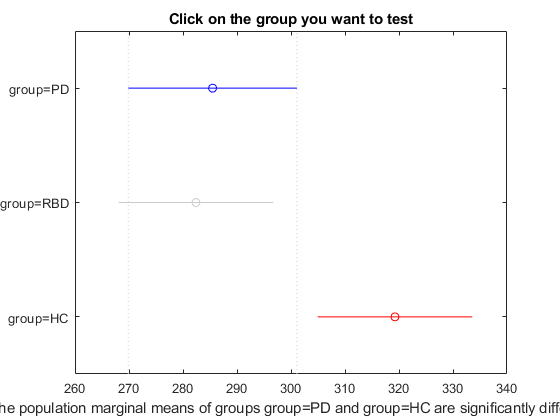

[c,m,h,gnames] = multcompare(stats);

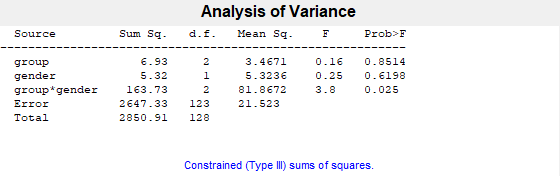



anovan(data_adj.AST_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

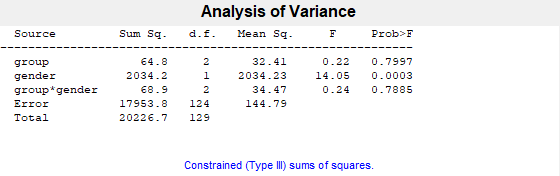


anovan(data_adj.GVI_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

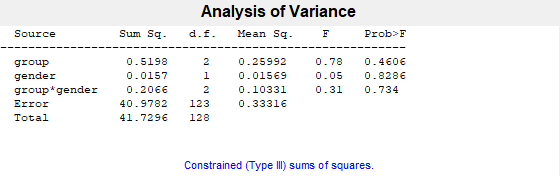


anovan(data_adj.DUF_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

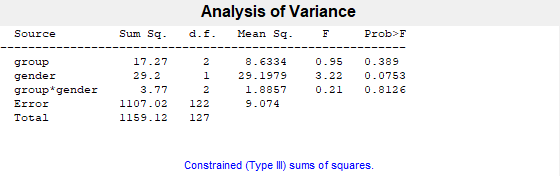


anovan(data_adj.RLR_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

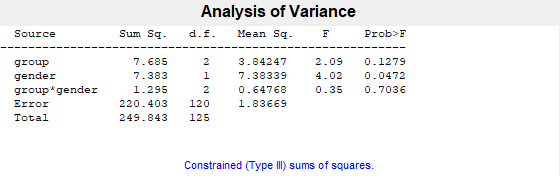


anovan(data_adj.PIR_M,{groups, gender},'varnames',{'group','gender'},'model','interaction');

#### Závěr: pohlaví zkresluje výsledek -> separace podle pohlaví

## Gender separation

female_ind = gender == 'F';
male_ind = ~female_ind;

data_female = data(female_ind,:);
data_male = data(male_ind,:);

groups_female = groups(female_ind);
groups_male = groups(male_ind);

data_f_M(:,1:12) = data_female(:,19:30);
data_f_M.Properties.VariableNames{1,1} = 'EST_M';
data_f_M.Properties.VariableNames{1,2} = 'RST_M';
data_f_M.Properties.VariableNames{1,3} = 'AST_M';
data_f_M.Properties.VariableNames{1,4} = 'DPI_M';
data_f_M.Properties.VariableNames{1,5} = 'DVI_M';
data_f_M.Properties.VariableNames{1,6} = 'GVI_M';
data_f_M.Properties.VariableNames{1,7} = 'DUS_M';
data_f_M.Properties.VariableNames{1,8} = 'DUF_M';
data_f_M.Properties.VariableNames{1,9} = 'RLR_M';
data_f_M.Properties.VariableNames{1,10} = 'PIR_M';
data_f_M.Properties.VariableNames{1,11} = 'RSR_M';
data_f_M.Properties.VariableNames{1,12} = 'LRE_M';


data_m_M(:,1:12) = data_male(:,19:30);
data_m_M.Properties.VariableNames{1,1} = 'EST_M';
data_m_M.Properties.VariableNames{1,2} = 'RST_M';
data_m_M.Properties.VariableNames{1,3} = 'AST_M';
data_m_M.Properties.VariableNames{1,4} = 'DPI_M';
data_m_M.Properties.VariableNames{1,5} = 'DVI_M';
data_m_M.Properties.VariableNames{1,6} = 'GVI_M';
data_m_M.Properties.VariableNames{1,7} = 'DUS_M';
data_m_M.Properties.VariableNames{1,8} = 'DUF_M';
data_m_M.Properties.VariableNames{1,9} = 'RLR_M';
data_m_M.Properties.VariableNames{1,10} = 'PIR_M';
data_m_M.Properties.VariableNames{1,11} = 'RSR_M';
data_m_M.Properties.VariableNames{1,12} = 'LRE_M';


## Females

[pf,tbl,stats] = anova1(data_f.RST_M, groups_female,"off");pf

pf = 0.1069


[pf,tbl,stats] = anova1(data_f.AST_M, groups_female,"off");pf

pf = 0.1649


[pf,tbl,stats] = anova1(data_f.GVI_M, groups_female,"off");pf

pf = 0.9811


[pf,tbl,stats] = anova1(data_f.DUF_M, groups_female,"off");pf

pf = 0.5973


[pf,tbl,stats] = anova1(data_f.RLR_M, groups_female,"off");pf

pf = 0.6955


[pf,tbl,stats] = anova1(data_f.PIR_M, groups_female,"off");pf

pf = 0.8416

### Závěr: u žen nejsou skupiny rozlišitelné, možná nízkým počtem vzorků (jen 9 na každou skupinu)

## Males

[pm,tbl,stats] = anova1(data_m_M.RST_M, groups_male,"off");pm

pm = 6.9871e-04

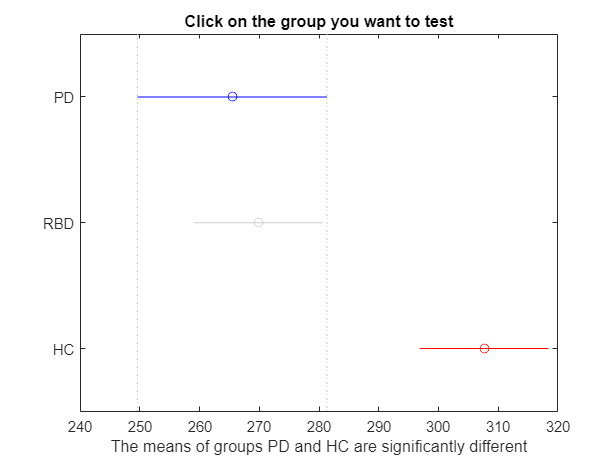

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = anova1(data_m_M.AST_M, groups_male,"off");pm

pm = 0.0781

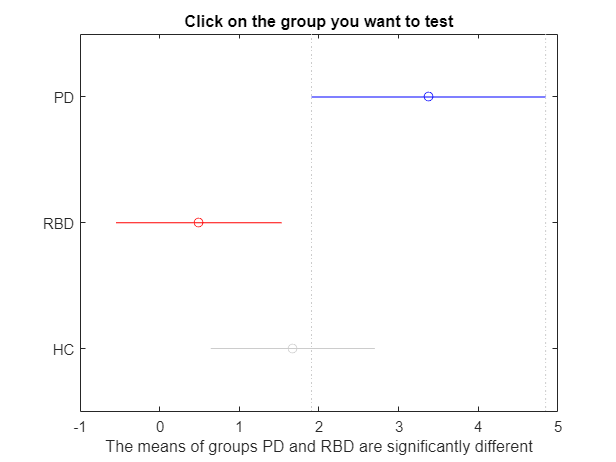

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = anova1(data_m_M.GVI_M, groups_male,"off");pm

pm = 0.3648

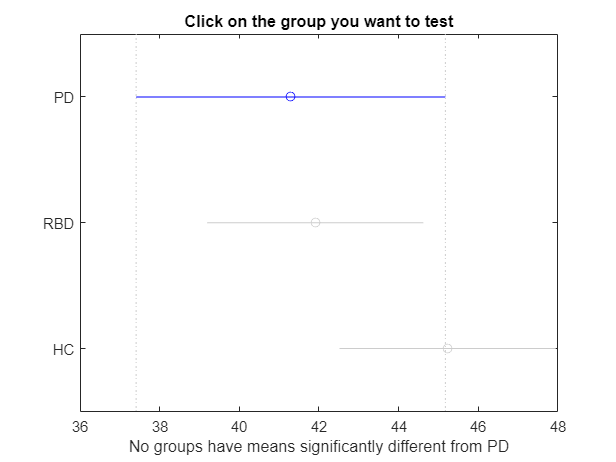

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = anova1(data_m_M.DUF_M, groups_male,"off");pm

pm = 0.5734

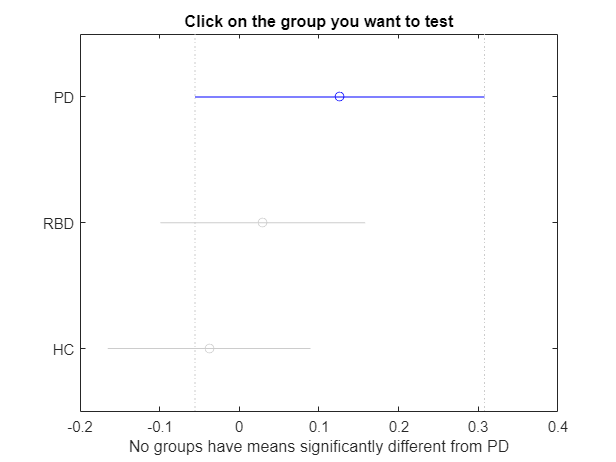

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = anova1(data_m_M.RLR_M, groups_male,"off");pm

pm = 0.3002

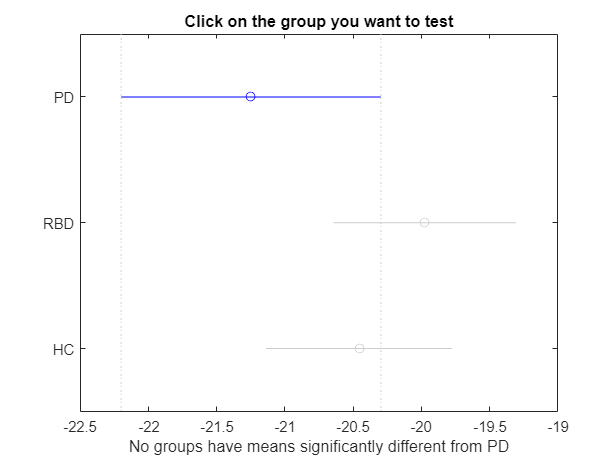

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = anova1(data_m_M.PIR_M, groups_male,"off");pm

pm = 0.0020

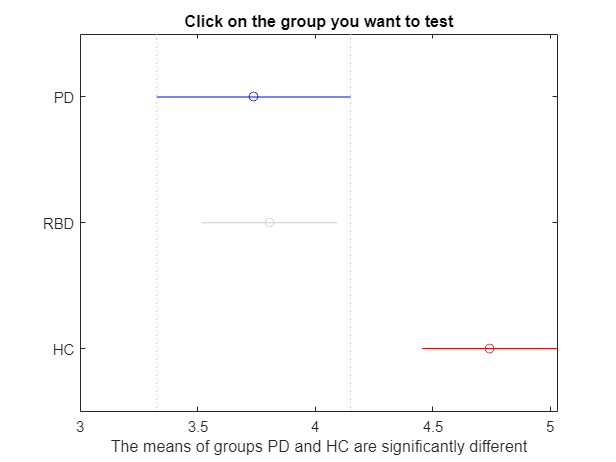

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");

## MANOVA - kombinace čtení-monolog

[d,p] = manova1([data_m_M.RST_M, data_m_R.RST_R], groups_male)

[d,p] = manova1([data_m_M.AST_M, data_m_R.AST_R], groups_male)

[d,p] = manova1([data_m_M.GVI_M, data_m_R.GVI_R], groups_male)

[d,p] = manova1([data_m_M.DUF_M, data_m_R.DUF_R], groups_male)

[d,p] = manova1([data_m_M.RLR_M, data_m_R.RLR_R], groups_male)

[d,p] = manova1([data_m_M.PIR_M, data_m_R.PIR_R], groups_male)


### stejné výsledky jako ANOVA

## KRUSKAL-WALLIS (all parameters)


[pm,tbl,stats] = kruskalwallis(data_m_M.EST_M, groups_male,"off");pm

pm = 0.0360

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


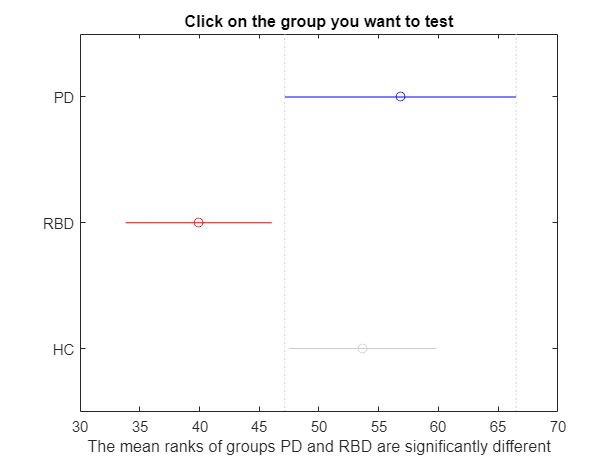

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.RST_M, groups_male,"off");pm

pm = 7.9597e-04

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


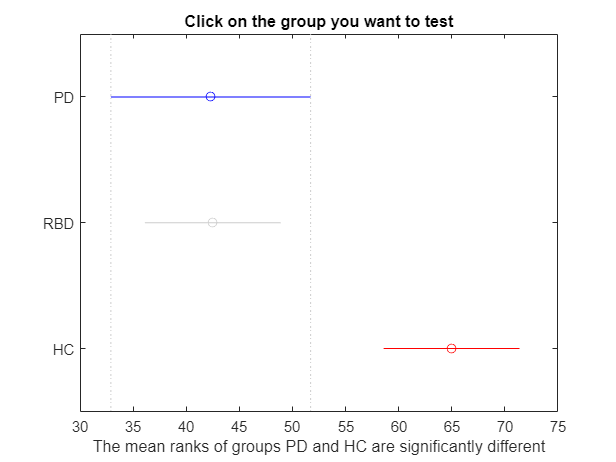

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.AST_M, groups_male,"off");pm

pm = 0.1035

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


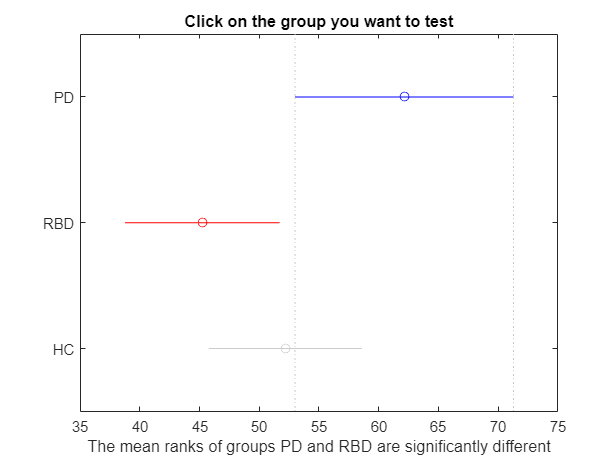

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.DPI_M, groups_male,"off");pm

pm = 0.0016

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


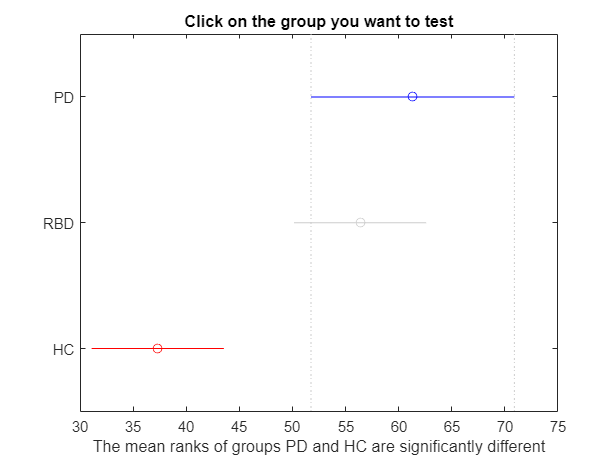

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.DVI_M, groups_male,"off");pm

pm = 0.1477

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


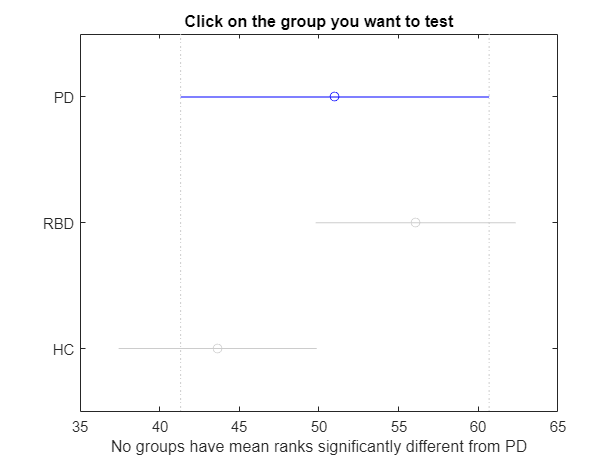

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.GVI_M, groups_male,"off");pm

pm = 0.5380

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


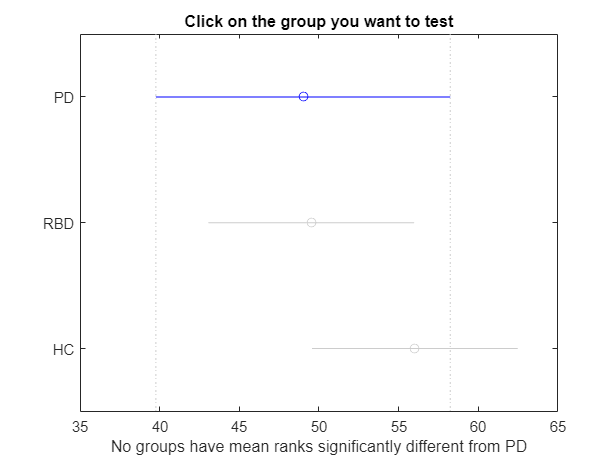

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.DUS_M, groups_male,"off");pm

pm = 0.0115

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


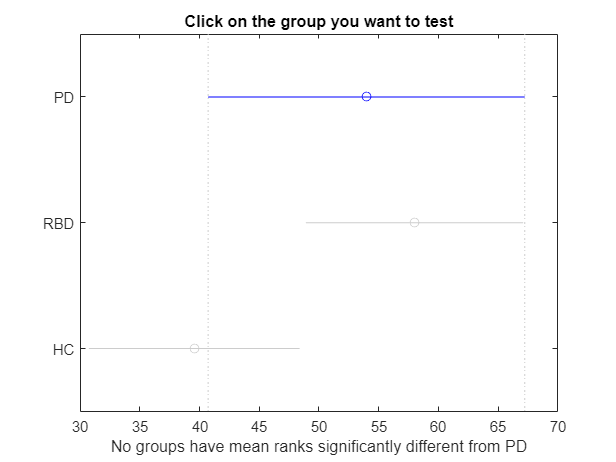

[c,m,h,gnames] = multcompare(stats,"Alpha",0.005,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.DUF_M, groups_male,"off");pm

pm = 0.6476

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


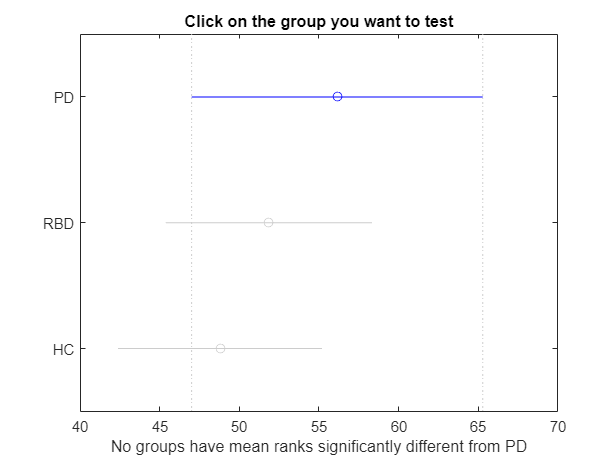

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.RLR_M, groups_male,"off");pm

pm = 0.1931

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


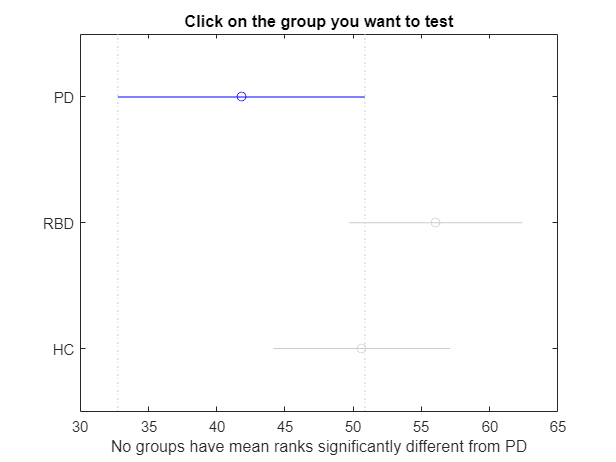

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.PIR_M, groups_male,"off");pm

pm = 0.0055

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


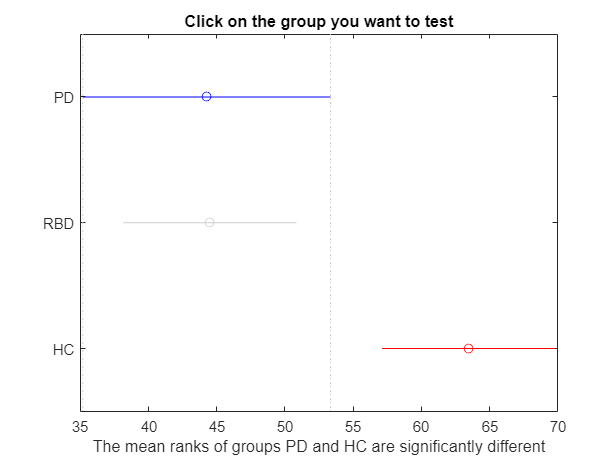

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.RSR_M, groups_male,"off");pm

pm = 0.0826

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


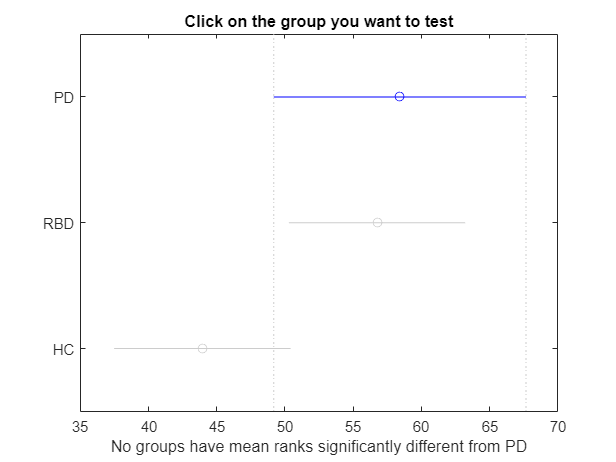

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");


[pm,tbl,stats] = kruskalwallis(data_m_M.LRE_M, groups_male,"off");pm

pm = 0.3625

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


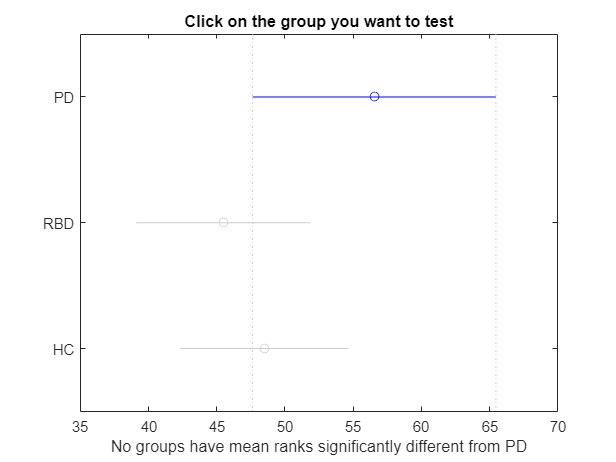

[c,m,h,gnames] = multcompare(stats,"Alpha",0.05,"CriticalValueType","lsd");